clear all;
close all;

%1 - problem-based
x = optimvar('x', 2, 1);
obj = 100 * (x(2) - x(1)^2)^2 + (1 - x(1))^2;
problemm = optimproblem('Objective',  obj, 'ObjectiveSense','minimize');
problemm.Constraints.cons1 = x(1)^2 + x(2)^2 <= 1;
problemm.Constraints.cons2 = x(1)^2 - x(2) <= 1;

x_0.x = [0; 0];

show(problemm)


  OptimizationProblem : 

	Solve for:
       x

	minimize :
       ((100 .* (x(2) - x(1).^2).^2) + (1 - x(1)).^2)


	subject to cons1:
       (x(1).^2 + x(2).^2) <= 1

	subject to cons2:
       (x(1).^2 - x(2)) <= 1
     



[sol, fval, exitflag, output] = solve(problemm, x0 = x_0)

Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


sol = struct with fields:
    x: [2×1 double]


fval = 0.0457

exitflag =     OptimalSolution


output = struct with fields:
              iterations: 22
               funcCount: 40
         constrviolation: 0
                stepsize: 6.9146e-06
               algorithm: 'interior-point'
           firstorderopt: 2.1705e-08
            cgiterations: 12
                 message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 2.170473e-08,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.'
            bestfeasible: [1×1 struct]
     objectivederivative: "reverse-AD"
    constraintderivative: "closed-form"
                  solver: '

sol.x

ans =     0.7864
    0.6177


%1 - solver-based
fun = @(x) 100 * (x(2) - x(1)^2)^2 + (1 - x(1))^2;
A = [];
b = [];
Aeq = [];
beq = [];
lb = [];
ub = [];
x0 = [0 0];
c = @cons;
x = fmincon(fun, x0, A, b, Aeq, beq, lb, ub, c)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =     0.7864    0.6177


% 2 - eq syst
options = optimset('Display', 'iter');
syst = @(x) [2 * x(1) - x(2) - exp(-x(1)); -x(1) + 2 * x(2) - exp(-x(2))];
[sol, fval, exitflag, output] = fsolve(syst, [5; 5], options)


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          3         49.8653                          5.03               1
     1          6         36.6236              1           4.34               1
     2          9         11.9568            2.5           2.64             2.5
     3         12        0.517775        3.20158          0.901            6.25
     4         15      0.00167893       0.406517         0.0457               8
     5         18     1.87487e-08      0.0259714       0.000152               8
     6         21     2.34142e-18     8.7371e-05        1.7e-09               8

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function toleran

sol =     0.5671
    0.5671


fval = 1.0e-08 *

   -0.1082
   -0.1082


exitflag = 1

output = struct with fields:
       iterations: 6
        funcCount: 21
        algorithm: 'trust-region-dogleg'
    firstorderopt: 1.6956e-09
          message: 'Equation solved.↵↵fsolve completed because the vector of function values is near zero↵as measured by the value of the function tolerance, and↵the problem appears regular as measured by the gradient.↵↵<stopping criteria details>↵↵Equation solved. The sum of squared function values, r = 2.341418e-18, is less than↵sqrt(options.FunctionTolerance) = 1.000000e-03. The relative norm of the gradient of r,↵1.695638e-09, is less than options.OptimalityTolerance = 1.000000e-06.'


% 3 - min func
options = optimset('Display', 'iter');
fun = @f2min;
[sol, resnorm, residual, exitflag, output] = lsqnonlin(fun, [0.3, 0.4], [], [], options)


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          3         4171.31                      4.37e+04
     1          6         4171.31       0.282867       4.37e+04      
     2          9         690.077      0.0707167       8.84e+03      
     3         12         690.077       0.141433       8.84e+03      
     4         15         233.559      0.0353584       2.93e+03      
     5         18         152.199      0.0707167       1.33e+03      
     6         21         147.185      0.0707167       1.18e+03      
     7         24         125.595      0.0176792            142      
     8         27         125.595      0.0353584            142      
     9         30          124.69     0.00883959           31.2      
    10         33         124.496      0.0176792           57.3      
    11         36         124.366      0.0044198           5.12      
    12         39         124.36

sol =     0.2578    0.2578


resnorm = 124.3622

residual =     1.4118    2.6505    3.6654    4.3906    4.7408    4.6057    3.8428    2.2672   -0.3600   -4.3482


exitflag = 2

output = struct with fields:
    firstorderopt: 2.3895e-04
       iterations: 23
        funcCount: 72
     cgiterations: 0
        algorithm: 'trust-region-reflective'
         stepsize: 2.6976e-07
          message: 'Local minimum possible.↵lsqnonlin stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 2.697629e-07,↵is less than options.StepTolerance = 1.000000e-06.'


% 4 and 8 -- min func and its surface
options = optimset('Display', 'iter');
fun = @(x) -10 * x(1)^2 + 10 * x(2)^2 + 4 * sin(x(1) * x(2)) -2 * x(1) + x(1)^4;
[sol, resnorm, exitflag, output] = fminsearch(fun, [1, 1], options)

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          2.36588         
     1            3           1.5602         initial simplex
     2            5        -0.976901         expand
     3            7         -3.87702         expand
     4            9          -9.7243         expand
     5           11         -17.6296         expand
     6           13         -28.0412         expand
     7           15         -30.9359         reflect
     8           17         -30.9359         contract outside
     9           19         -30.9359         contract inside
    10           21         -30.9359         contract inside
    11           23         -30.9359         contract outside
    12           25         -31.1309         expand
    13           27         -31.1309         contract inside
    14           29         -31.1761         reflect
    15           31         -31.1761         contract outside
    16           33         -31.1761         cont

sol =     2.3066   -0.3323


resnorm = -31.1807

exitflag = 1

output = struct with fields:
    iterations: 36
     funcCount: 71
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


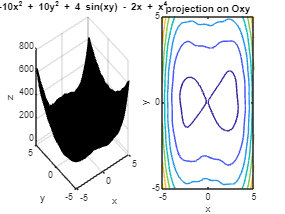


hold on;
close all;
[X, Y] = meshgrid(-5:0.1:5);
fun = @(x, y) -10 * x.^2 + 10 * y.^2 + 4 * sin(x .* y) - 2 * x + x.^4;
subplot(1, 2, 1);
surf(X, Y, fun(X, Y));
title('-10x^2 + 10y^2 + 4 sin(xy) - 2x + x^4');
xlabel('x'); ylabel('y'); zlabel('z');

subplot(1, 2, 2);
%pcolor(X, Y, fun(X, Y));
contour(X, Y, fun(X, Y));
xlabel('x'); ylabel('y');
title('projection on Oxy');
hold off;

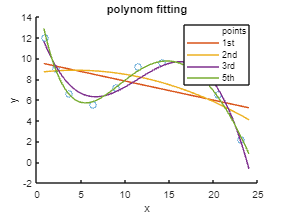

% 5 -fit a poly
close all;hold on;
x = [1, 2.2, 3.7, 6.4, 9, 11.5, 14.2, 17.8, 20.5, 23.2];
y = [12, 9, 6.6, 5.5, 7.2, 9.2, 9.6, 8.5, 6.5, 2.2];
plot(x, y, 'o');
xp = 0.8:0.1:24;
for p = [1 2 3 5]
    plot(xp, polyval(polyfit(x, y, p), xp));
end
xlabel('x'); ylabel('y');
legend("points", "1st", "2nd", "3rd", "5th");
title("polynom fitting");
hold off;

% 6 - table
table_ = readtable('table1.xlsx', 'PreserveVariableNames', true, 'ReadRowNames', true);
col = mean(table2array(table_), 2);
table_ = table_(1:end-1, 1);
table_.Properties.VariableNames = "Mean Value";
table_.("Mean Value") = [col(1:end-1, 1)]

table_ = 8×1 table
                          Mean Value
                          __________

    Arsenik tonn           0.0014436
    Kadmium tonn           0.0004946
    Chromium (Cr) tonn     0.0040149
    Copper tonn             0.028076
    Dioksin tonn          1.9713e-08
    Lead pb                0.0060866
    Mercure                0.0002907
    PAH-4                  0.0066721


writetable(table_, 'Pollutant.xlsx', 'WriteRowNames', true, 'WriteVariableNames', true);


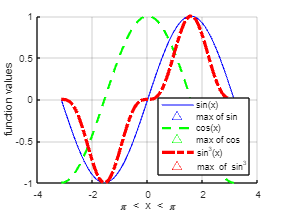

% 7 - plot
close all;
hold on
x = linspace(-pi, pi, 100);
plot(x, sin(x), 'LineStyle','-', LineWidth=1, Color="b")
[maxv, idx] = max(sin(x));
plot(x(idx), maxv, '^b', MarkerSize=8)
plot(x, cos(x), 'LineStyle','--', LineWidth=2, Color="g")
[maxv, idx] = max(cos(x));
plot(x(idx), maxv, '^g', MarkerSize=8)
plot(x, (sin(x)).^3, 'LineStyle','-.', LineWidth=3, Color="r")
[maxv, idx] = max((sin(x)).^3);
plot(x(idx), maxv, '^r', MarkerSize=8)

xlabel('\pi < x < \pi')
ylabel("function values")
legend("sin(x)", "max of sin", "cos(x)", "max of cos", "sin^3(x)", "max of sin^3", Location="southeast")
grid on;
hold off;